# P02: Señales discretas

Integrantes:

- Edgar Vargas Rodríguez

- Jaqueline Tinoco Vázquez

- Mauricio Paulo Peña Sánchez

## **Objetivo**

- Manipulación básica de MATLAB

- Gráficas de señales reales y complejas discretas

- Transformación de señales discretas (escalamientos y traslaciones)

## Introducción

Problema 1 de esta practica realizado con Python, lo podemos ver en el sigueinte [enlace](https://colab.research.google.com/drive/1zfnugi4nM2pc6A67EnRm6s3IFqk2IF3d?usp=sharing).

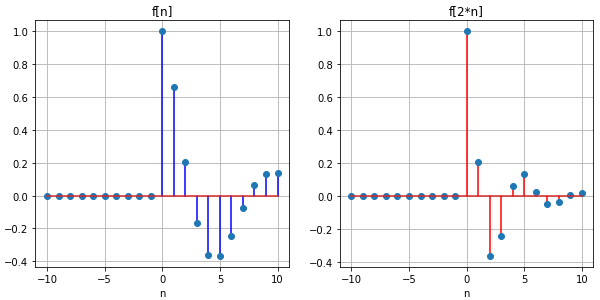

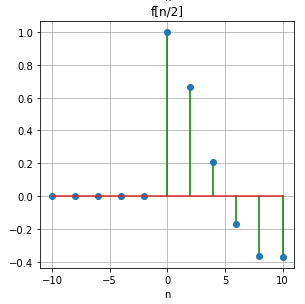

## Desarrollo

### Problema 1

Resuelve el problema 3.11-2

**3.11-2**.Consider the discrete-time function$f\left\lbrack n\right\rbrack =e^{-n/5} \cos \left(\pi n/5\right)u\left\lbrack n\right\rbrack$.Section 3.11 uses anonymous functions in describing DT signals.

`f = @(n) exp(-n/5).*cos(pi*n/5).*(n>=0);`

While this anonymous function operates correctly for a downsampling operation such as `f[2n]`, it does not operate correctly for an upsampling operation, such as `f[n/2]`. Modify the anonymous function `f` so that it also correctly accommodates upsampling operations. Test your code by computing and plotting` f(n/2) `over $\left(-10\le n\le 10\right)$.

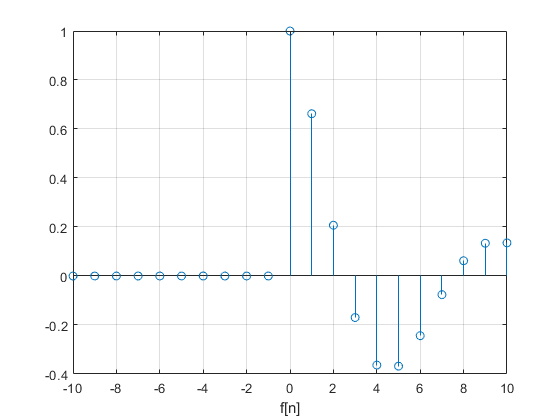

clc, clear all, close all
f = @(n) exp(-n/5).*cos(pi*n/5).*(n>=0);
n = -10:10;

%subplot(3,1,1);
figure
stem(n,f(n))
grid on
xlabel('f[n]');

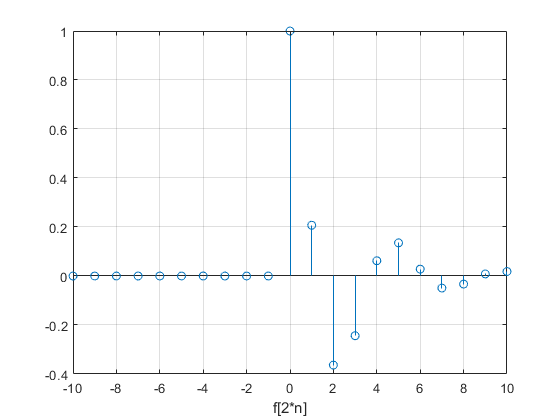


n = -10:10;
%subplot(3,1,2);
figure
stem(n,f(2*n))
grid on
xlabel('f[2*n]');

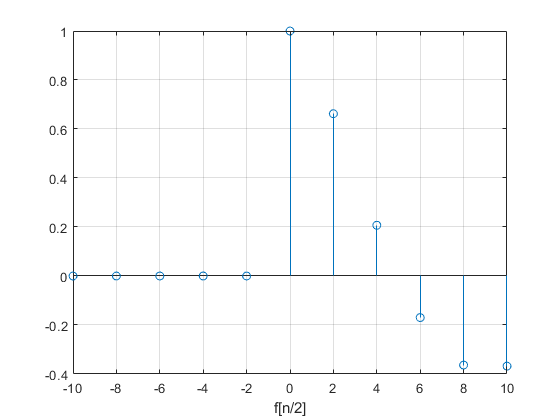


%subplot(3,1,3);
figure
n = -10:2:10;
g = @(n) exp(-n/5).*cos(pi*n/5).*(n>=0);
stem(n,g(n/2))
grid on
xlabel('f[n/2]');

### Problema 2

Resuelve el problema 3.2-7

**3.2-7**. For the signal shown in Fig. P3.1-1b, sketch the

following signals:

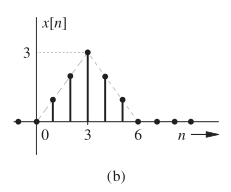

Primero generamos la señal $x\left\lbrack n\right\rbrack$

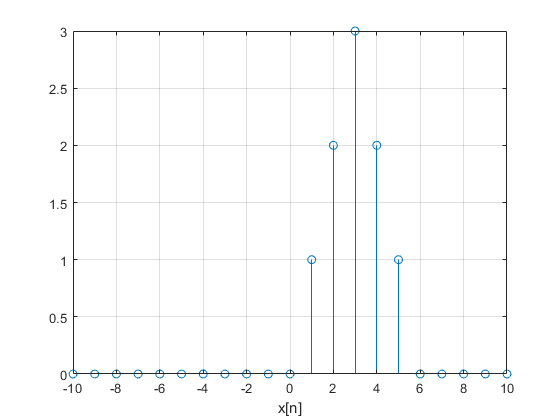

clc, clear all, close all
x = @(n) n.*(n>=0).*(n<=3) + (-n+6).*(n>=4).*(n<=6);
n = -10:10;

figure
stem(n,x(n))
grid on
xlabel('x[n]');

a) $x\left\lbrack -n\right\rbrack$

n = -10:5;
subplot(3,2,1)
stem(n,x(-n))
grid on
xlabel('a) x[-n]');

b) x[n + 6]

subplot(3,2,2)
stem(n,x(n+6))
grid on
xlabel('b) x[n+6]');

c) x[n − 6]

n = 0:15;
subplot(3,2,3)
stem(n,x(n-6))
grid on
xlabel('d) x[n-6]');

d) x[3*n]

n = -10:10;
subplot(3,2,4)
stem(n,x(3*n))
grid on
xlabel('d) x[3*n]');

e) x[n / 3]

n = 0:3:20;
subplot(3,2,5)
stem(n,x(n/3))
grid on
xlabel('e) x[n/3]');

f) x[3 − n]

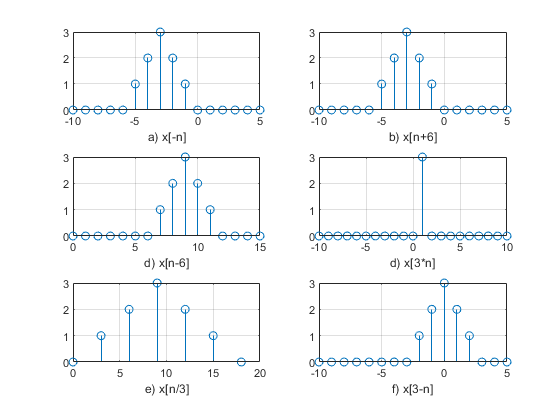

n = -10:5;
subplot(3,2,6)
stem(n,x(3-n))
grid on
xlabel('f) x[3-n]');

### Problema 3

Resuelva el problema 3.11-6

**3.11-6. **Suppose a vector x exists in the MATLAB workspace, corresponding to a finite-duration DT signal $x\left\lbrack n\right\rbrack$

a) Write a MATLAB function that, when passed vector x, computes and returns Ex, the energy of x[n]. 

(b) Write a MATLAB function that, when passed vector x, computes and returns Px, the power of x[n]. Assume that x[n] is periodic and that vector x contains data for an integer number of periods of x[n].

### Problema 4

Con los programas desarrollados en el punto 3, resuelva 3.1-1 c) y 3.1-2 b)

**3.1-1. **Find the energy of the signals depicted in Fig. P3.1-1. c)

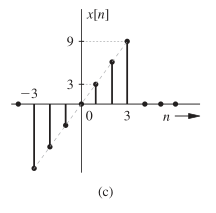

Ex = function_energy([-9,-6,-3,0,3,6,9])

Ex = 252

**3.1-2.** Find the power of the signals illustrated in Fig. P3.1-2. b)

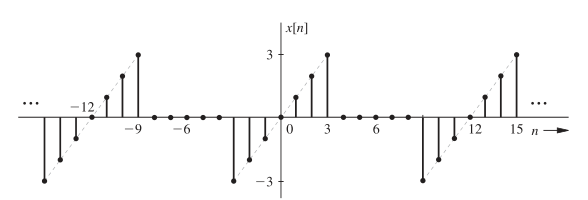

Px = function_power([-3,-2,-1,0,1,2,3,0,0,0,0,0])

Px = 2.3333

### Problema 5

Construya una app que permita (consultar los ejemplos preconstruidos):

- Gráficar señales en tiempo discreto reales, el usuario ingresa la definición de la señal en el formato especifico

- El usuario puede definir el intervalo de la gráfica

- El usuario puede seleccionar el tipo de transformación (horizontal, vertical o combinación) que desee realizar a la señal, la app deberá mostrar la gráfica de esta transformación.

- Se adjunta una imagen de la app a la práctica, y el archivo de la app.

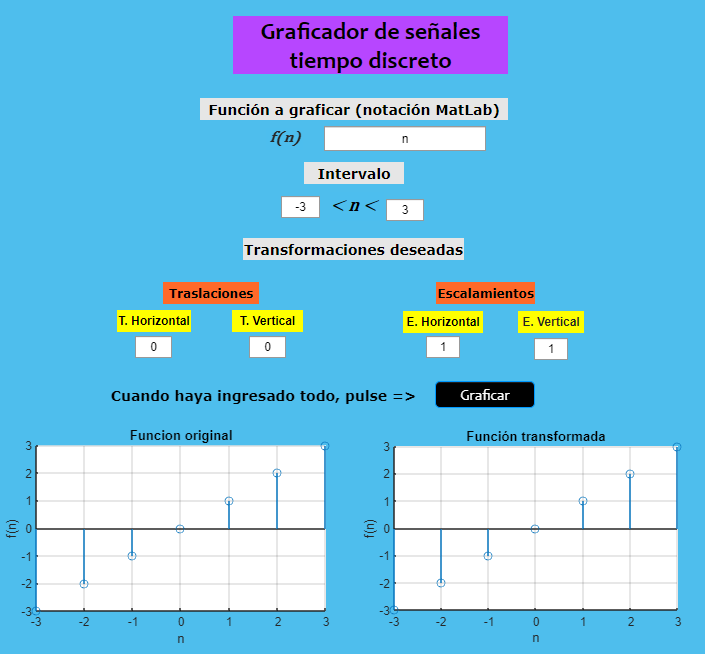

Link de descarga: [aplicación](https://drive.google.com/file/d/1v33vBjmXUylL9d7sJ9LTREZaG96zL1-A/view?usp=sharing)

## Referencias

Lathi, E. B. P., & Green, A. P. R. (2017). Linear Systems and Signals (3rd ed.). Oxford University Press, USA.